# 근궤적 제어기 설계 입문 (한글판)

원문 : Control Tutorials for MATLAB and Simulink — Introduction: Root Locus Controller Design 한글 정리 : 제어시스템설계 · 충남대학교 자율운항시스템공학과

이 문서에서 하는 것

- **근궤적**이 무엇인지 이해한다

- MATLAB 으로 근궤적을 그린다

- 근궤적 위에서 **이득을 하나 골라** 사양을 만족시킨다

오늘 쓰는 MATLAB 명령

- `rlocus` — 근궤적 그리기

- `sgrid` — 사양 영역 겹치기

- `feedback` — 폐루프 만들기

- `step`, `stepinfo` — 검증

clc; close all;
s = tf('s');

## 1. 근궤적이란

**어떤 파라미터(보통 비례이득 **$K$**)를 **$0$** 에서 **$\infty$** 까지 바꿀 때 폐루프 극점이 지나가는 자리를 전부 모아 그린 것**입니다.

아래는 단위 피드백 구조입니다. 되먹임 경로에 무엇이 있든 절차는 똑같습니다.

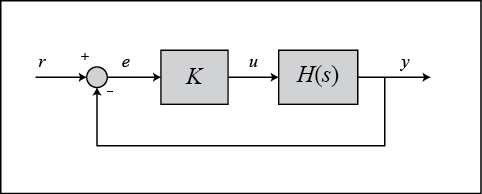

비례이득만 있는 폐루프

## 1-1. 왜 이 그림이 유용한가

폐루프 전달함수는 이렇습니다.


$$\frac{Y(s)}{R(s)} = \frac{K\,H(s)}{1 + K\,H(s)}$$


따라서 폐루프 극점은 다음을 만족하는 $s$ 입니다.


$$1 + K\,H(s) = 0$$


$H(s) = b(s)/a(s)$ 로 쓰면 이렇게 바뀝니다.


$$a(s) + K\,b(s) = 0$$


여기서 두 가지가 바로 보입니다.

- $K \rightarrow 0$ 이면 $a(s) = 0$, 즉 **개루프 극점**에서 출발한다

- $K \rightarrow \infty$ 이면 $b(s) = 0$, 즉 **개루프 영점**으로 끝난다

- 영점이 모자라면 남는 가지는 **무한대로** 뻗어 나간다

외울 규칙이 아니라 식에서 바로 나오는 결과입니다.

## 2. 직접 점을 찍어 보기

원문에서는 슬라이더로 $K$ 를 바꾸며 점을 찍습니다. 여기서는 여러 $K$ 를 한 번에 찍어 보겠습니다.


$$H(s) = \frac{s+2}{s^2 + 2s + 3}$$


H = (s + 2)/(s^2 + 2*s + 3);

figure('Position',[80 80 950 420]);
tiledlayout(1,2,'TileSpacing','compact');

nexttile
hold on; grid on;
pl = pole(H);  zr = zero(H);
plot(real(pl), imag(pl), 'bx', 'MarkerSize', 14, 'LineWidth', 3);
plot(real(zr), imag(zr), 'bo', 'MarkerSize', 12, 'LineWidth', 2.5);
for K = [0.5 1 2 4 8 16 32]
    r = pole(feedback(K*H, 1));
    plot(real(r), imag(r), '.', 'Color',[0.85 0.2 0.15], 'MarkerSize', 18);
end
xline(0,'k-'); yline(0,'k-');
xlim([-6 1]); ylim([-3 3]);
xlabel('실수부'); ylabel('허수부');
title('이득을 바꿔 가며 폐루프 극점을 찍어 보면');

nexttile
rlocus(H); grid on;
xlim([-6 1]); ylim([-3 3]);
title('rlocus 는 그 점들을 이어 준다');

왼쪽 그림의 빨간 점들이 오른쪽 선 위에 그대로 놓입니다. `rlocus` 는 점 찍는 일을 자동으로 해 주는 명령일 뿐입니다.

- 파란 $\times$ — 개루프 극점 (출발점, $K = 0$)

- 파란 $\circ$ — 개루프 영점 (도착점, $K = \infty$)

fprintf('=== 출발점과 도착점 ===\n');
fprintf('  개루프 극점 (K = 0 일 때 폐루프 극점) : %s\n', mat2str(round(pole(H).',3)));
fprintf('  개루프 영점 (K -> 무한대에서 도착)    : %s\n', mat2str(round(zero(H).',3)));
for K = [0.01 100]
    fprintf('  K = %6.2f 일 때 폐루프 극점 : %s\n', K, ...
            mat2str(round(pole(feedback(K*H,1)).',3)));
end
fprintf('\n');

## 3. 근궤적에서 이득 고르기

근궤적 위의 점 하나하나가 **어떤 **$K$** 에 대한 폐루프 극점**입니다. 그러니 원하는 자리를 고르면 그에 해당하는 $K$ 가 정해집니다.

어디를 골라야 하는가 — 4주차에서 배운 대로 사양을 $s$ 평면의 **영역**으로 바꿉니다.

- 오버슈트 조건 $\rightarrow$ 감쇠비 $\zeta \ge \zeta_{min}$ $\rightarrow$ **부채꼴**

- 정착시간 조건 $\rightarrow$ 실수부 $\le -4/t_s$ $\rightarrow$ **세로선 왼쪽**

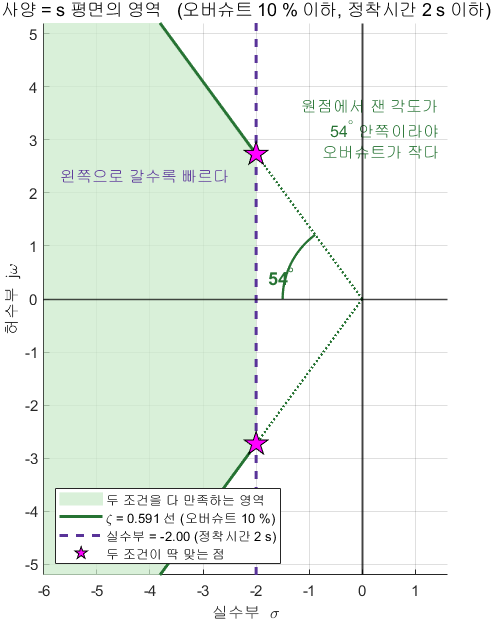

사양의 합격 영역 (오버슈트 10 %, 정착시간 2 s)

## 3-1. sgrid 로 겹쳐 그리기

`sgrid(zeta, wn)` 은 등감쇠비 직선과 등고유진동수 원을 현재 그림 위에 덧그립니다.

**반드시 rlocus 다음에 부르십시오.**

[zmin, wmin, starget] = spec2pole(10, 2);
fprintf('=== 사양 변환 (오버슈트 10 %%, 정착시간 2 s) ===\n');
fprintf('  zeta >= %.4f , wn >= %.4f\n', zmin, wmin);
fprintf('  목표 극점 : %+.3f %+.3fj\n\n', real(starget), imag(starget));

figure;
rlocus(H); hold on;
sgrid(zmin, wmin);
plot(real(starget), imag(starget), 'p', 'MarkerSize', 16, ...
     'MarkerFaceColor','m', 'MarkerEdgeColor','k');
plot(real(starget), -imag(starget), 'p', 'MarkerSize', 16, ...
     'MarkerFaceColor','m', 'MarkerEdgeColor','k');
xlim([-6 1]); ylim([-4 4]); grid on;
title('궤적과 사양 영역 (별표 = 목표 극점)');

## 3-2. 이득을 숫자로 찾기

원문은 `rlocfind` 로 마우스를 찍습니다. 편하지만 두 가지가 불편합니다.

- 손이 떨리면 값이 달라진다

- 스크립트를 자동으로 돌릴 수 없다 (클릭을 기다리며 멈춘다)

그래서 이 과목에서는 `rl_scan` 으로 이득을 촘촘히 훑어 표로 만듭니다.

T = rl_scan(1, H, linspace(0.1, 30, 400), true);
ok = T.stable & T.OS <= 10 & T.ts <= 2;

fprintf('=== 사양을 만족하는 이득 ===\n');
if any(ok)
    fprintf('  K = %.2f ~ %.2f\n', min(T.K(ok)), max(T.K(ok)));
    sub = T(ok,:);
    fprintf('     K     OS[%%]   ts[s]   max|u|\n');
    fprintf('  ------  ------  ------  -------\n');
    for i = round(linspace(1, height(sub), 4))
        fprintf('  %6.2f  %6.2f  %6.2f  %7.2f\n', ...
                sub.K(i), sub.OS(i), sub.ts(i), sub.umax(i));
    end
    Kpick = sub.K(round(height(sub)/2));
else
    fprintf('  만족하는 K 가 없습니다. 보상기가 필요합니다.\n');
    Kpick = 5;
end
fprintf('\n');

## 4. 고른 이득을 검증한다

설계는 여기서 끝나지 않습니다. **반드시 검증**해야 합니다.

근궤적에서 이득을 고를 때 쓰는 공식은 "극점 두 개, 영점 없음" 을 가정한 것입니다. 실제 시스템은 극점이 더 있거나 영점이 있으므로 어긋날 수 있습니다.

Tcl  = feedback(Kpick*H, 1);
info = stepinfo(Tcl);
t = (0:0.01:6)';
[u, ~, umax] = ctrl_input(Kpick, H, t);

fprintf('=== 검증 (K = %.2f) ===\n', Kpick);
fprintf('  오버슈트 %.2f %%   (요구 10 이하)\n', info.Overshoot);
fprintf('  정착시간 %.3f s    (요구 2 이하)\n', info.SettlingTime);
fprintf('  폐루프 극점 : %s\n', mat2str(round(pole(Tcl).',3)));
fprintf('  최대 제어입력 %.2f\n\n', umax);

figure('Position',[80 80 950 400]);
tiledlayout(1,2,'TileSpacing','compact');
nexttile
plot(t, step(Tcl, t), 'LineWidth', 2); hold on;
yline(1,'k--'); yline(1.1,'r:'); xline(2,'r:');
grid on; xlabel('시간 [s]'); ylabel('출력');
legend('출력','목표','오버슈트 한계','정착시간 한계','Location','southeast');
title('계단응답으로 검증');
nexttile
plot(t, u, 'LineWidth', 2); grid on;
xlabel('시간 [s]'); ylabel('제어입력 u');
title('제어입력도 반드시 본다');

## 5. 이득만으로 안 될 때

근궤적은 **정해진 길**입니다. 이득은 그 길 위에서 점을 옮길 뿐입니다. 길이 사양 영역을 비껴가면 이득으로는 어떻게 해도 안 됩니다.

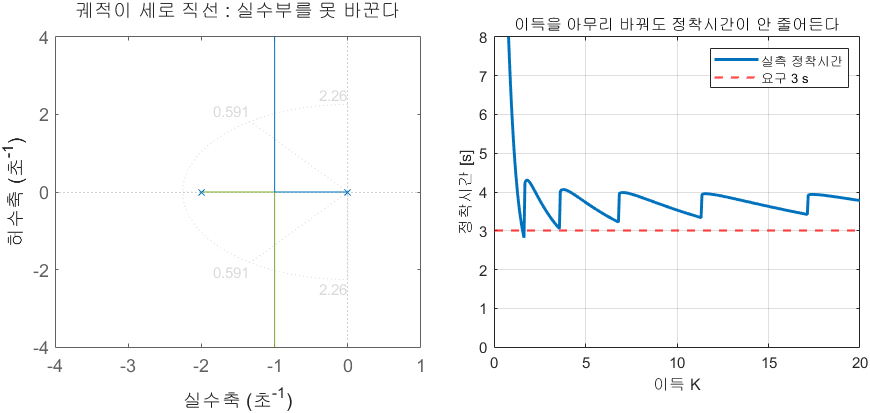

궤적이 세로 직선이면 정착시간을 못 바꾼다

그럴 때는 **길 자체를 옮겨야** 합니다. 방법은 제어기에 극점이나 영점을 더하는 것입니다.

- **영점을 더한다** $\rightarrow$ 궤적이 그쪽(왼쪽)으로 당겨진다 $\rightarrow$ **PD, Lead**

- **원점에 극점을 더한다** $\rightarrow$ 타입이 올라 오차가 사라진다 $\rightarrow$ **PI, Lag**

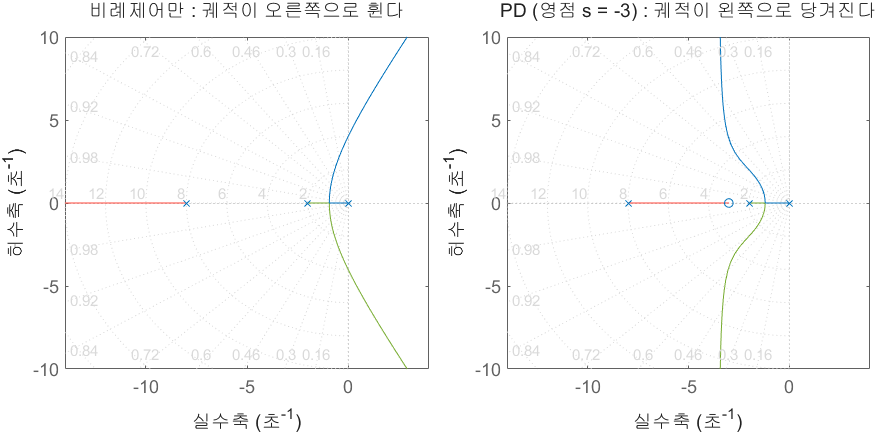

영점 하나로 궤적이 통째로 왼쪽으로 옮겨진다

## 6. 정리

- 근궤적 = 이득을 바꿀 때 폐루프 극점이 지나가는 **길**

- 궤적은 개루프 **극점에서 출발**해 개루프 **영점에서 끝난다**

- 사양을 $s$ 평면의 영역으로 바꾸고 `sgrid` 로 겹쳐 이득을 고른다

- **고른 뒤에는 반드시 stepinfo 로 검증하고 제어입력도 확인한다**

- 이득만으로 안 되면 극점·영점을 더해 **길 자체를 옮긴다**

이 과목의 6, 7 주차 내용과 그대로 이어집니다.